## **ECS 174 Computer Vision, Spring 2020, Problem Set 1**

Cai Li     913432338

**Problem 1**

**1. Give an example of how one can exploit the associative property of convolution to more **

**efficiently filter an image. **

As an example, if we want to smooth the image with a gaussian filter and then find its edges with a sobel filter. What we can do is convolute the gaussian filter and sobel fitler first and then convolute the image with this combined filter.

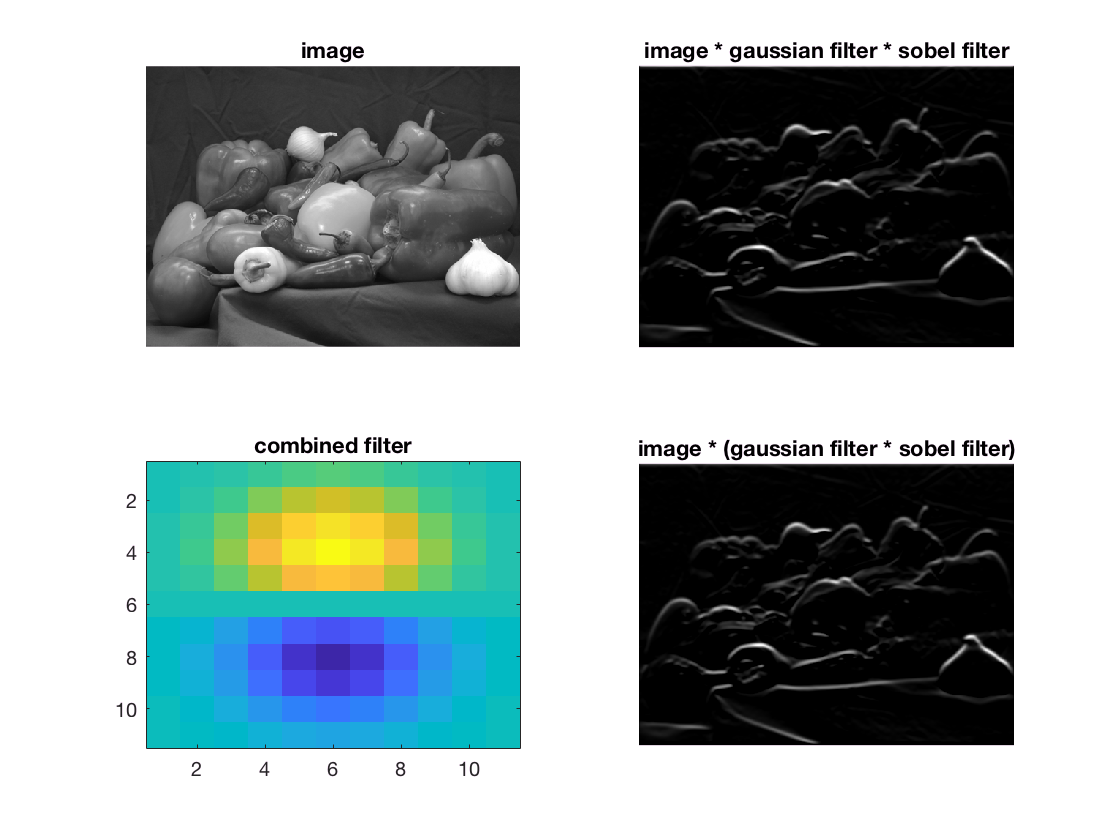

img = imread('peppers.png');
img = rgb2gray(img);
img = double(img);
h_gaussian = fspecial('gaussian', [11,11], 2);
h_sobel = fspecial('sobel');
img_gaus = imfilter(img, h_gaussian, 'conv');
img_gaus_sobel = imfilter(img_gaus, h_sobel, 'conv');
h_combined = imfilter(h_gaussian, h_sobel, 'conv');
img_combined = imfilter(img, h_combined, 'conv');
figure;
subplot(2,2,1); imshow(img, [0, 255]); title('image');
subplot(2,2,2); imshow(img_gaus_sobel, [0,255]); title('image * gaussian filter * sobel filter');
subplot(2,2,3); imagesc(h_combined); title('combined filter');
subplot(2,2,4); imshow(img_combined, [0,255]); title('image * (gaussian filter * sobel filter)'); 

**2. This is the input image: **`[1 0 0 1 1 0 0 1]`**. What is the result of dilation with a structuring **

**element **`[1 1 1]?`

After the dilation, the result is [1, 1, 1, 1, 1, 1, 1, 1]

**3. Describe a possible flaw in the use of additive Gaussian noise to represent image noise. **

**4. Design a method that takes video data from a camera perched above a conveyor belt at an automotive equipment manufacturer, and reports any flaws in the assembly of a part. Your response should be a list of concise, specific steps, and should incorporate several techniques covered in class thus far. Specify any important assumptions your method makes.**

Transform the images to the same view using affine transformation;

Segment out the automotive assembly from the image and put the assembly in an image of the same size;

Extract the features using a filter bank;

Get a reference image of the same size of an qualified part. Extract the features using the same filter bank;

Subtract the feature maps of the standard part to the feature maps of the test part. The large difference area suggests that there are flaws.